## Import the data

#### Import CSV file

clearvars;
% filename = 'Data/20230322_1/400V_1.0MSs_5ohm_17_20230322103933251.5V_5ohm_-3V_ALL.csv';
% filename = 'Data/20230322_1/400V_1.0MSs_5ohm_17_20230322104327251.5V_5ohm_-3V_ALL.csv';
filename = 'Data/FFT_Test/Pulse_60_Vds_350_Vgson_175_Vgsoff_30_ALL_20230425140645918.csv'

filename = 'Data/FFT_Test/Pulse_60_Vds_350_Vgson_175_Vgsoff_30_ALL_20230425140645918.csv'

data = readtable(filename);

#### Data parsing

data = renamevars(data, "Labels", "Time");
t = data.Time;
Vgs = data.Vgs;
Vds = data.Vds;
Id = data.Id; 

## Plot the imported data

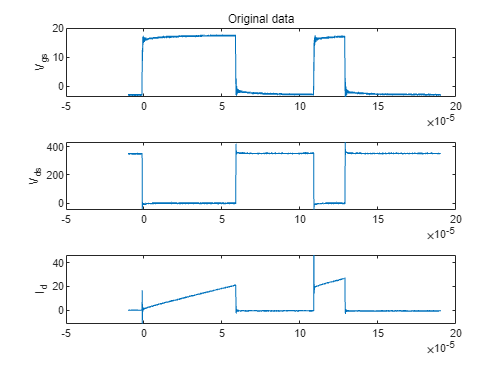

figure;

subplot(3,1,1);
plot(t, Vgs);
ylabel("V_{gs}");
title("Original data");

subplot(3,1,2);
plot(t, Vds);
ylabel("V_{ds}");

subplot(3,1,3);
plot(t, Id);
ylabel("I_d");

## Find the switching transient

#### Eliminate the mean value in Vgs

to find the switching transient by means of finding the zerocrossing of Vgs waveform.

Vgs_mean = mean(Vgs)

Vgs_mean = 5.1797

Vgs_zeromean = Vgs - Vgs_mean;

#### Find the zerocrossing

min_gap = 10000; % Arbitrary value

zero_crossings = Find_zeroCrossing(Vgs_zeromean, min_gap);
assert(length(zero_crossings) == 4, "Error: Switching transient detection failed")

% Interpolate the time values corresponding to the zero crossings
zero_crossing_times = interp1(1:length(t), t, zero_crossings);

#### Parse the zerocrossing point to switching transient

zero_crossing_names = {"Charging"; "Turn-Off"; "Turn-On"; "End"}

zero_crossing_names = 4×1 cell 배열
    {["Charging"]}
    {["Turn-Off"]}
    {["Turn-On" ]}
    {["End"     ]}


st_time = containers.Map();
for i = 1:4
    st_time(zero_crossing_names{i}) = zero_crossing_times(i);
end
disp(keys(st_time))

    {'Charging'}    {'End'}    {'Turn-Off'}    {'Turn-On'}



disp(values(st_time))

    {[-1.1443e-06]}    {[1.2879e-04]}    {[5.8791e-05]}    {[1.0885e-04]}



#### Plot the zerocrossing 

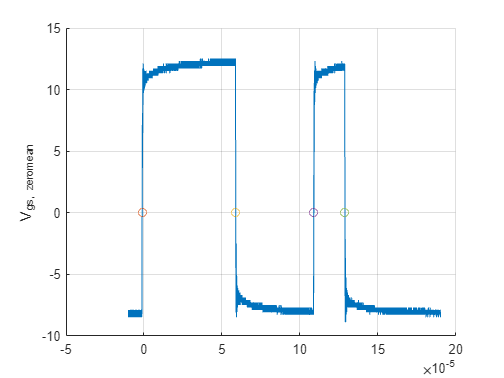

figure;
hold on;
plot(t, Vgs_zeromean);
scatter(zero_crossing_times, 0);
ylabel("V_{gs, zeromean}");
grid on;
hold off;

#### Find the switching transients

% st_time_range = 0.1 * [-1e-6 9e-6];
st_time_range = 0.1 * [2e-6 12e-6];

Turn-Off transient

turnoff_time_range = st_time("Turn-Off") + st_time_range;
index_turnoff = (turnoff_time_range(1) < t) & (t < turnoff_time_range(2));
t_turnoff = t(index_turnoff);
Vgs_turnoff = Vgs(index_turnoff);
Vds_turnoff = Vds(index_turnoff);
Id_turnoff = Id(index_turnoff);

Turn-On transient 

turnon_time_range = st_time("Turn-On") + st_time_range;
index_turnon = (turnon_time_range(1) < t) & (t < turnon_time_range(2));
t_turnon = t(index_turnon);
Vgs_turnon = Vgs(index_turnon);
Vds_turnon = Vds(index_turnon);
Id_turnon = Id(index_turnon);

Plot at the transient

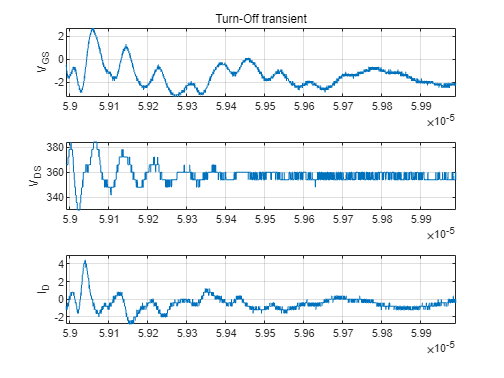

figure;
subplot(3,1,1)
plot(t_turnoff, Vgs_turnoff);
ylabel("V_{GS}");
xlim(turnoff_time_range)
title("Turn-Off transient")
grid on;
subplot(3,1,2)
plot(t_turnoff, Vds_turnoff);
ylabel("V_{DS}");
xlim(turnoff_time_range)
grid on;
subplot(3,1,3)
plot(t_turnoff, Id_turnoff);
ylabel("I_{D}");
xlim(turnoff_time_range)
grid on;

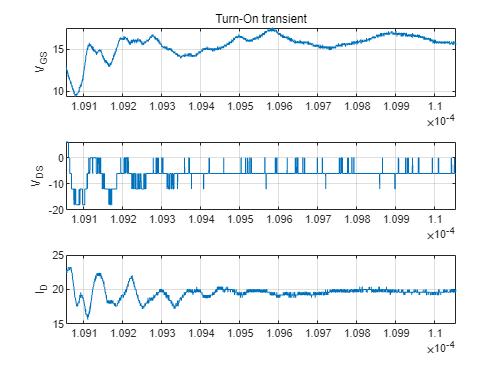

figure;
subplot(3,1,1)
plot(t_turnon, Vgs_turnon);
ylabel("V_{GS}");
xlim(turnon_time_range)
title("Turn-On transient")
grid on;
subplot(3,1,2)
plot(t_turnon, Vds_turnon);
ylabel("V_{DS}");
xlim(turnon_time_range)
grid on;
subplot(3,1,3)
plot(t_turnon, Id_turnon);
ylabel("I_{D}");
xlim(turnon_time_range)
grid on;

## Perform FFT

fs = length(t)/(t(length(t)) - t(1))

fs = 6.2500e+09

For Turn-off transient

fft_Id_turnoff = fft(Id_turnoff);
fft_Vds_turnoff = fft(Vds_turnoff);
fft_Vgs_turnoff = fft(Vgs_turnoff);

For Turn-on transient

fft_Id_turnon = fft(Id_turnon);
fft_Vds_turnon = fft(Vds_turnon);
fft_Vgs_turnon = fft(Vgs_turnon);

`Calculate the corresponding frequency vector`

N_turnoff = length(t_turnoff);
f_turnoff = (0:(N_turnoff-1))*(fs/N_turnoff);
N_turnon = length(t_turnon);
f_turnon = (0:(N_turnon-1))*(fs/N_turnon);

#### Plot the FFT result

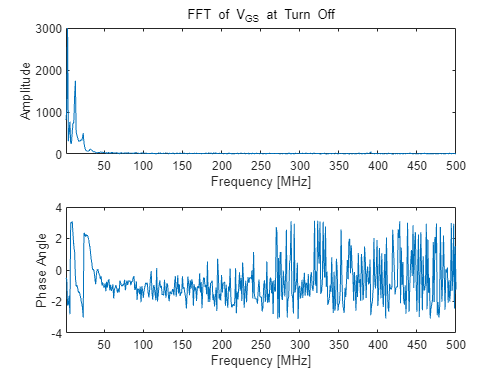

f_lim = [1e6 500e6];

figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Vgs_turnoff));
title("FFT of V_{GS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Vgs_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

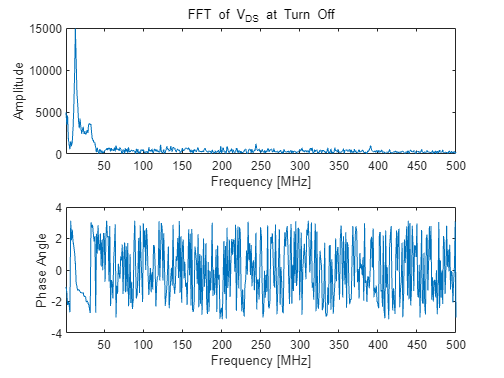

figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Vds_turnoff));
title("FFT of V_{DS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Vds_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

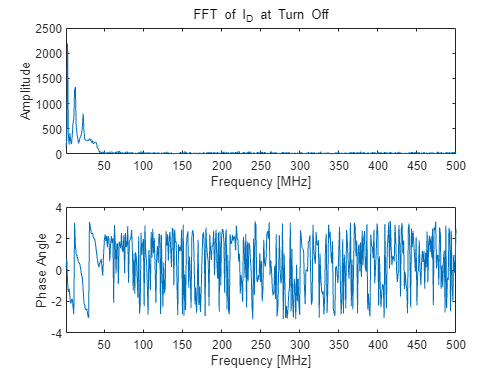


figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Id_turnoff));
title("FFT of I_D at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Id_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

At lower frequency

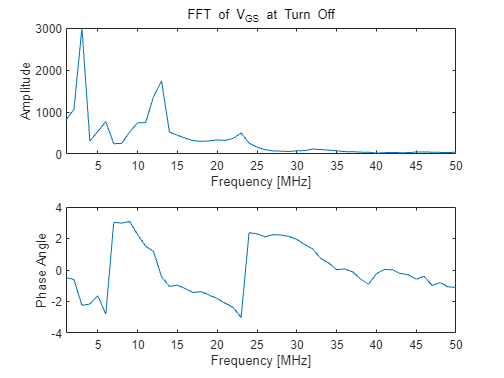

f_lim = [1e6 50e6];

figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Vgs_turnoff));
title("FFT of V_{GS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Vgs_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

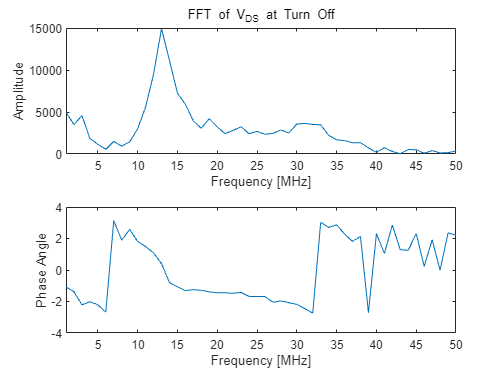

figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Vds_turnoff));
title("FFT of V_{DS} at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Vds_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

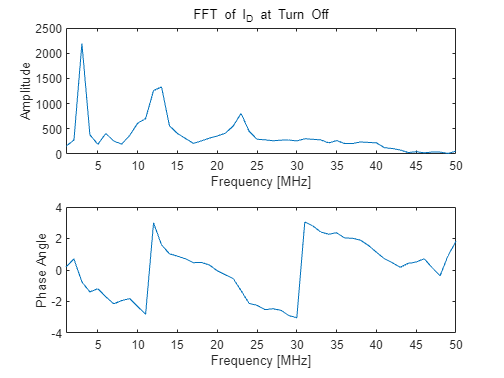


figure;
subplot(2,1,1);
plot(f_turnoff/1e6, abs(fft_Id_turnoff));
title("FFT of I_D at Turn Off");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnoff/1e6, angle(fft_Id_turnoff));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

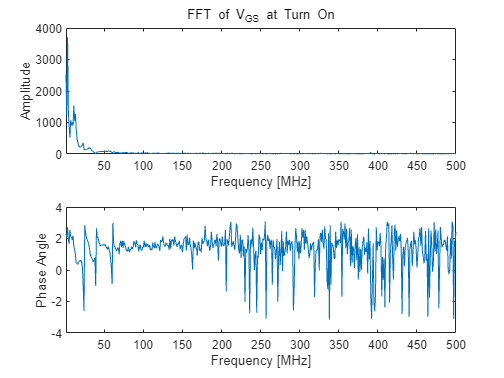

f_lim = [1e6 500e6];

figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Vgs_turnon));
title("FFT of V_{GS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Vgs_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

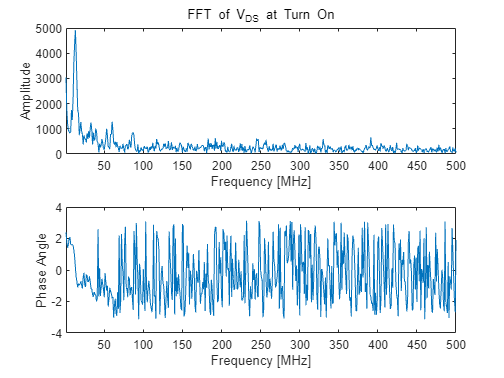

figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Vds_turnon));
title("FFT of V_{DS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Vds_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

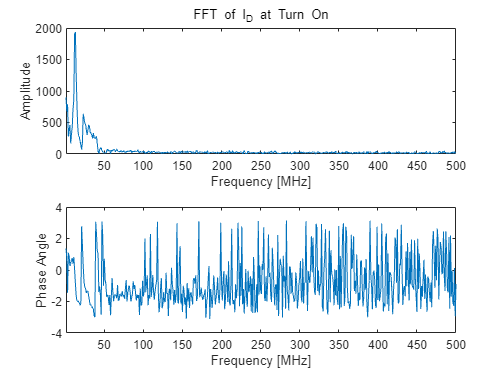


figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Id_turnon));
title("FFT of I_D at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Id_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

At lower frequency

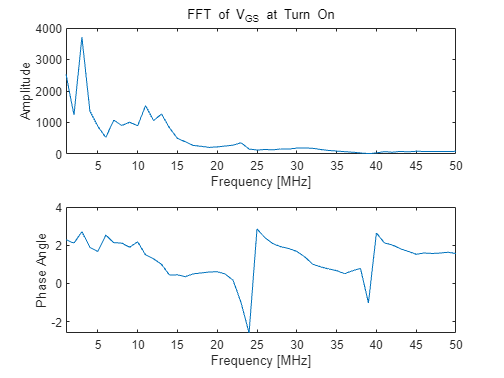

f_lim = [1e6 50e6];

figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Vgs_turnon));
title("FFT of V_{GS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Vgs_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

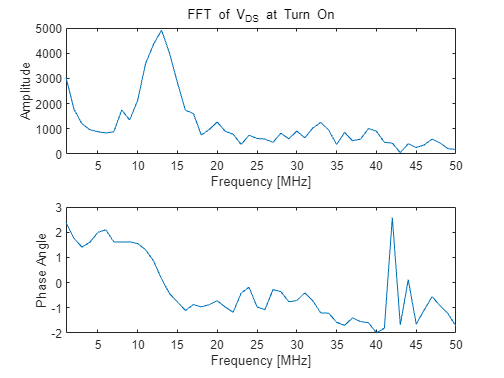

figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Vds_turnon));
title("FFT of V_{DS} at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Vds_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);

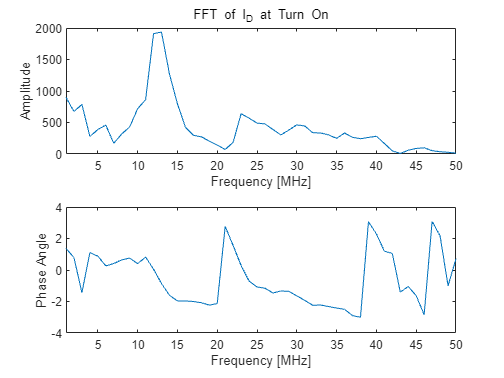


figure;
subplot(2,1,1);
plot(f_turnon/1e6, abs(fft_Id_turnon));
title("FFT of I_D at Turn On");
xlabel("Frequency [MHz]");
ylabel("Amplitude");
xlim(f_lim/1e6);

subplot(2,1,2);
plot(f_turnon/1e6, angle(fft_Id_turnon));
xlabel("Frequency [MHz]");
ylabel("Phase Angle");
xlim(f_lim/1e6);